## The impact of the EU-ETS on unemployment in France

### 0. Housekeeping

clear;
close all;

### 1. Data Importation 

Import Data Series:

- `GDP: OECD/QNA/FRA.B1_GE.CQRSA.Q`

- `Inflation: OECD/QNA/FRA.B1_GE.DNBSA.Q`

- `Unemployment: OECD/MEI/FRA.LRUN64TT.STSA.Q`

- `Carbon emissions: Eurostat/sdg_13_10/A.GHG.TOTX4_MEMONIA.T_HAB.FR`

`Every serie is SA.`

% GDP, deflator, unemployment
[output1,~,T1] = call_dbnomics('OECD/QNA/FRA.B1_GE.CQRSA.Q','OECD/QNA/FRA.B1_GE.DNBSA.Q', 'OECD/MEI/FRA.LRUN64TT.STSA.Q');

% Carbon emissions
[output2,~,T2] = call_dbnomics('Eurostat/sdg_13_10/A.GHG.TOTX4_MEMONIA.T_HAB.FR');

% Carbon prices
tt_import = readtimetable("carbon_prices_062009_122019.xlsx");

### 2. Data treatment

Retime emissions and carbon prices to quarterly data

% Carbon emissions
dates = datetime(output2(:,1), 'ConvertFrom', 'datenum');
values = output2(:,2);
tt = timetable(dates, values);

ttQ = retime(tt, 'quarterly', 'linear');
output2Q = [datenum(ttQ.dates), ttQ.values];

% Carbon prices
carbon_prices = retime(tt_import(:,4),"quarterly","mean");
outputQ_cp = [datenum(carbon_prices.dates), carbon_prices.pe_obs2];

Merge datasets

output = merged_output(output1, output2Q);
output = merged_output(output, outputQ_cp)

output = 1.0e+05 *

    7.2318    1.0870    0.0004       NaN       NaN       NaN
    7.2327    1.1152    0.0004       NaN       NaN       NaN
    7.2336    1.1458    0.0004       NaN       NaN       NaN
    7.2345    1.1689    0.0004       NaN       NaN       NaN
    7.2355    1.2061    0.0004       NaN       NaN       NaN
    7.2364    1.2468    0.0004       NaN       NaN       NaN
    7.2373    1.2949    0.0004       NaN       NaN       NaN
    7.2382    1.3507    0.0005       NaN       NaN       NaN
    7.2391    1.4061    0.0005       NaN       NaN       NaN
    7.2400    1.4538    0.0005       NaN       NaN       NaN


Drop Na values and get index

idx = find(~isnan(sum(output(:,2:end),2)));
output = output(idx,:);
T = T1(idx);

Normalize to 2015 prices

id2015 = find(T==2015);
def = output(:,3)/output(id2015,3);

### 3. Create variables of interest

gy_obs  = diff(log(output(:,2)./(def))); % Output growth
pi_obs  = diff(log(def)); % Inflation growth
u_obs = diff(log(output(:,4))); % Unemployment growth
ges_obs = diff(log(output(:,5))); % Emission growth
cp_obs = diff(log(output(:,6)));
T = T(2:end);

### 4. Test stationnarity

1 means that we reject null hypothesis (ADF = 1 => stationnarity ; KPSS = 1 => non-stationnarity)

GDP growth: stationnary

[h,pValue,stat,cValue] = adftest(gy_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -3.5165

cValue = -1.9475

[h,pValue,stat,cValue] = kpsstest(gy_obs)

h = logical
   0


pValue = 0.0957

stat = 0.1213

cValue = 0.1460

Inflation: non-stationnary

[h,pValue,stat,cValue] = adftest(pi_obs)

h = logical
   1


pValue = 0.0163

stat = -2.4317

cValue = -1.9475

[h,pValue,stat,cValue] = kpsstest(pi_obs) %pval = 1% => probablement car tendance haussière en fin de série mais si on s'arrête fin 2019, le problème devrait être réglé

h = logical
   0


pValue = 0.1000

stat = 0.1078

cValue = 0.1460

Unemployment: non-stationnary

[h,pValue,stat,cValue] = adftest(u_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -5.7496

cValue = -1.9475

[h,pValue,stat,cValue] = kpsstest(u_obs)

h = logical
   0


pValue = 0.1000

stat = 0.0905

cValue = 0.1460

Carbon emissions:

[h,pValue,stat,cValue] = adftest(ges_obs)

h = logical
   0


pValue = 0.2275

stat = -1.1453

cValue = -1.9475

[h,pValue,stat,cValue] = kpsstest(ges_obs)

h = logical
   1


pValue = 0.0100

stat = 0.2549

cValue = 0.1460

Prix du carbon

[h,pValue,stat,cValue] = adftest(cp_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -4.4954

cValue = -1.9475

[h,pValue,stat,cValue] = kpsstest(cp_obs)

h = logical
   0


pValue = 0.1000

stat = 0.1052

cValue = 0.1460

### 5. Plot variables

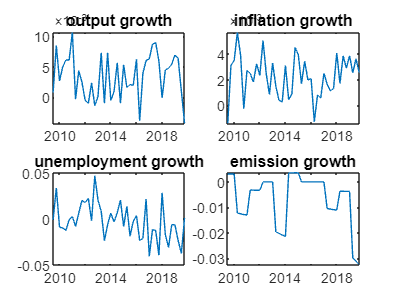

figure;
subplot(2,2,1)
plot(T,gy_obs)
xlim([min(T) max(T)]);
title('output growth')
subplot(2,2,2)
plot(T,pi_obs)
xlim([min(T) max(T)]);
title('inflation growth')
subplot(2,2,3)
plot(T,u_obs)
xlim([min(T) max(T)]);
title('unemployment growth')
subplot(2,2,4)
plot(T,ges_obs)
xlim([min(T) max(T)]);
title('emission growth')

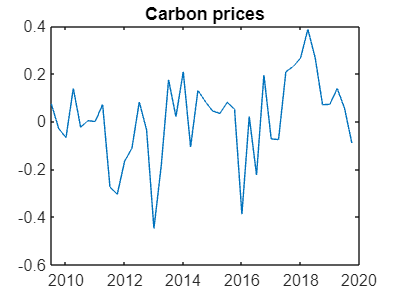


figure;
plot(T,cp_obs)
title('Carbon prices')

### 6. Save variables in a matrix 

save myobs T gy_obs pi_obs u_obs ges_obs cp_obs;

model = ar(cp_obs,1);  % Estimates AR(1) using Yule-Walkermatlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'ID', 'focused', 'ar');
ar_coeff = -model.A(2);
disp(['Estimated AR(1) coefficient: ', num2str(ar_coeff)]);

Estimated AR(1) coefficient: 0.3273
